%% LQR and LQI Controller

clc;
close all;
clear all;


%% Part 1: LQR (Continuous)

% 1.1) Continuous Time Plant

A = [0    1    0;
     0    0    1;
    -505 -111  -7];

B = [0;
     0;
     1];

C = [1 0 0];
D = 0;

% Eigenvalues
eig(A)

ans =   -5.0000 + 0.0000i
  -1.0000 +10.0000i
  -1.0000 -10.0000i



% Controllability
rank(ctrb(A,B))

ans = 3


% Observability
rank(obsv(A,C))

ans = 3


% System
Gp_ss = ss(A,B,C,D);

figure,step(Gp_ss);
grid on


%% 1.2) Solve for LQR Gain (Method 1, Manual Cal)

% X_dot = AX + BU
%
% J = âˆ«0âˆžâ€‹ (x'Qx + u'Ru) dt
% 
% A'P + PA âˆ’ PBR^-1B'P + Q = 0
% 
% K = R^âˆ’1 B' P


Q = 10^0 * [10^0  0     0;
             0     10^0  0;
             0     0     10^0];

R = 10^-3;

% Solve Riccati Equation (P+)
[P,~,~] = care(A, B, Q, R);

disp('Riccati Solution P+ = ')

Riccati Solution P+ = 


disp(P)

   47.4313   14.2543    0.0010
   14.2543    6.4125    0.0935
    0.0010    0.0935    0.0282




% Compute Gain manually
K = inv(R)*B'*P;

disp('Gain K = ')

Gain K = 


disp(K)

    0.9891   93.5228   28.1574




% Closed loop
Acl = A - B*K;  % Xdot = (A - BK)X

disp('Closed loop eigenvalues = ')

Closed loop eigenvalues = 


eig(Acl)

ans =  -28.6314 + 0.0000i
  -3.2630 + 2.6505i
  -3.2630 - 2.6505i



% System simulation
Gp_ss_cl1 = ss(Acl, B, C, D);

close all;
figure, step(Gp_ss_cl1)
grid on
title('LQR using CARE (manual K)')


%% Add feedforward Gain correction
DCGain_CL = dcgain(Gp_ss_cl1);
FF = 1/DCGain_CL; % --> u = -Kx + FF*r, FF = DCGain_CL^-1


Bcl = B * FF;
Acl = A - B*K;
Ccl = C;
Dcl = 0;

Gp_ss_cl1_FF = ss(Acl, Bcl, Ccl, Dcl);

figure,step(Gp_ss, Gp_ss_cl1, Gp_ss_cl1_FF);
grid on
title('LQR with Feedforward (Step -> 1)');


%% 1.3) Use default LQR command

% [K,S,P] = lqr(sys,Q,R,N);  K-->Gain, S-->P (Sol Ricatti), P-->CLPoles

[K2, P2, Poles_CL2] = lqr(Gp_ss, Q, R, []);

% System simulation
Gp_ss_cl2 = ss(A - B*K2, B, C, D);

close all;
figure, step(Gp_ss_cl2)
grid on
title('LQR using CARE (manual K)')


% Add feedforward Gain correction
DCGain_CL2 = dcgain(Gp_ss_cl2);
FF2 = 1/DCGain_CL2; % --> u = -Kx + FF*r, FF = DCGain_CL^-1


Bcl2 = B * FF2;
Acl2 = A - B*K2;
Ccl2 = C;
Dcl2 = 0;

Gp_ss_cl2_FF = ss(Acl2, Bcl2, Ccl2, Dcl2);

figure,step(Gp_ss, Gp_ss_cl2, Gp_ss_cl2_FF);
grid on
title('LQR with Feedforward (Step -> 1)');



figure,step(Gp_ss_cl1_FF, 'b'); hold on;
step(Gp_ss_cl2_FF, 'r--'); grid on;



%% Part 2: Discrete LQR

% [K,S,e] = dlqr(A, B, Q, R, N)

Ts = 10^-3;

Gpz_ss = c2d(Gp_ss, Ts, 'zoh');




Qz = 0.1 * [10^0  0     0;
             0     10^0  0;
             0     0     10^0];

Rz = 10^3;

[K3, P3, Poles_CL3] = dlqr(Gpz_ss.A,  Gpz_ss.B,  Qz, Rz, [])

K3 = 1.0e-04 *

   -0.0510    0.9299    0.2057


P3 = 1.0e+04 *

    4.7549    1.0399    0.0000
    1.0399    0.2944    0.0094
    0.0000    0.0094    0.0021


Poles_CL3 =    0.9990 + 0.0100i
   0.9990 - 0.0100i
   0.9950 + 0.0000i



Ad = Gpz_ss.A;
Bd = Gpz_ss.B;
Cd = Gpz_ss.C;
Dd = Gpz_ss.D;

% Closed loop
Acld1 = Ad - Bd*K3;

disp('Closed loop eigenvalues = ')

Closed loop eigenvalues = 


eig(Acld1)

ans =    0.9950 + 0.0000i
   0.9990 + 0.0100i
   0.9990 - 0.0100i


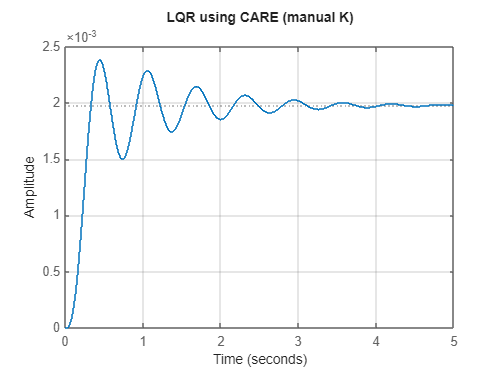


% System simulation
Gpz_ss_cl1 = ss(Acld1, Bd, Cd, Dd, Ts);

close all;
figure, step(Gpz_ss_cl1)
grid on
title('LQR using CARE (manual K)')

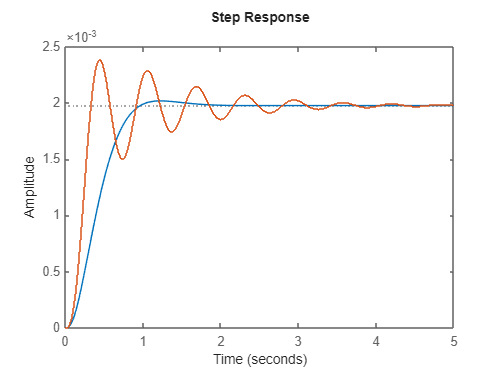


figure,step(Gp_ss_cl1, Gpz_ss_cl1);

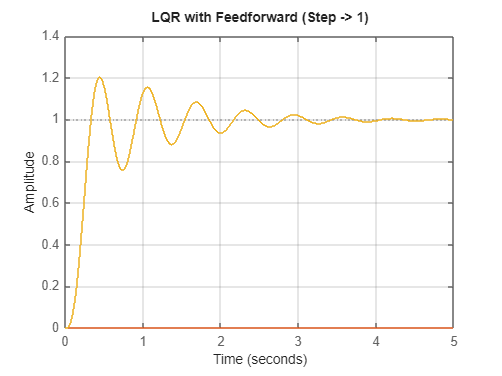



%% Add feedforward Gain correction
DCGain_CLZ2 = dcgain(Gpz_ss_cl1);
FFz2 = 1/DCGain_CLZ2; % --> u = -Kx + FF*r, FF = DCGain_CL^-1


Bclz2 = Bd * FFz2;
Aclz2 = Ad - Bd*K3;
Cclz2 = Cd;
Dclz2 = 0;

Gpz_ss_cl1_FF = ss(Aclz2, Bclz2, Cclz2, Dclz2, Ts);

figure,step(Gpz_ss, Gpz_ss_cl1, Gpz_ss_cl1_FF);
grid on
title('LQR with Feedforward (Step -> 1)');

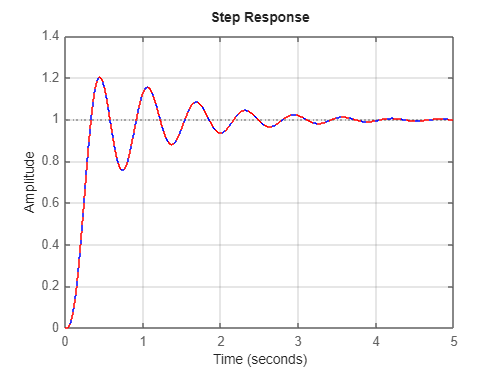




figure,step(Gpz_ss_cl1_FF, 'b'); hold on;
step(Gpz_ss_cl1_FF, 'r--'); grid on;





%% Part 3: LQI 

% Further Reading LQI command 
% https://www.mathworks.com/help/control/ref/ss.lqi.html


